clear; clc;
syms P
tau_p=0.04;
k_p=1.2;
k_c=5; %5,10,40
s=tf('s');
P=k_p/s/(tau_p*s+1);

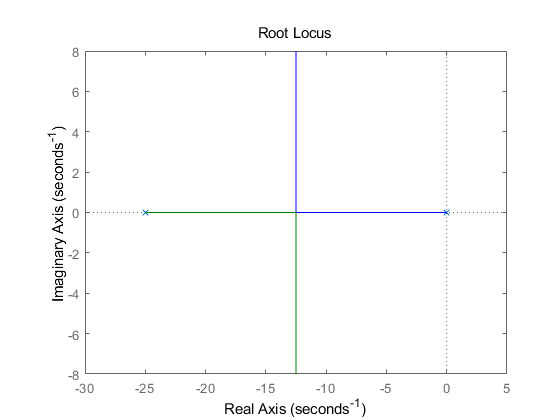

figure()
rlocus(P)

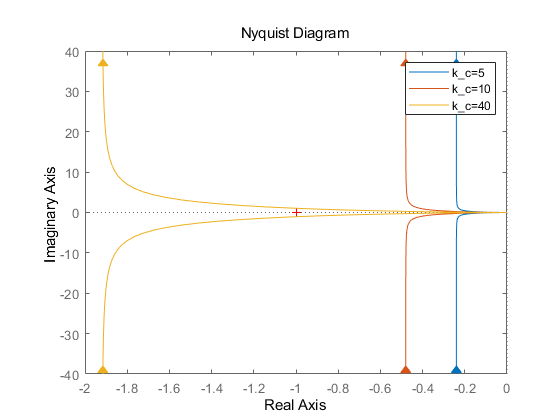

figure()
hold on
nyquist(k_c*P)
nyquist(2*k_c*P)
nyquist(8*k_c*P)
legend('k_c=5','k_c=10','k_c=40')
hold off

**2_5**

clear;
syms tt zeta omegan s
load('Data.mat')

r=1-exp(-80*tt);
rs=laplace(r,tt,s);
T=omegan^2/(s^2+2*zeta*omegan*s+omegan^2);
ys=T*rs;
yy=ilaplace(ys,s,tt);
% some curve fitting steps...  omegan =5.497  (5.433,5.561) zeta = 0.9165 (0.9046, 0.9285)

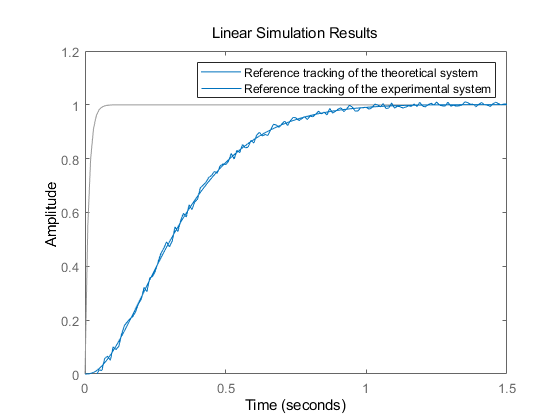

w=5.497; z=0.9165;
ss=tf('s');
r=1-exp(-80*t);
TT=w^2/(ss^2+2*z*w*ss+w^2);
figure()
hold on
lsim(TT,r,t)
plot(t,y,'linewidth',0.5)
legend('Reference tracking of the theoretical system', ...
       'Reference tracking of the experimental system');
hold off

**2_6**

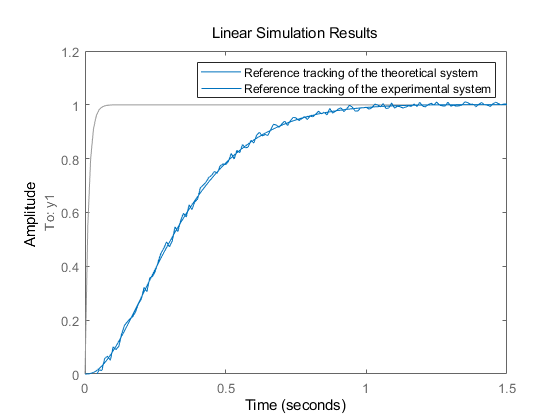

clear;
load('Data.mat');
r=1-exp(-80*t);
data=iddata(y,r,t(2)-t(1));
sys=tfest(data,2,0);
figure()
hold on
lsim(sys,r,t)
plot(t,y,'linewidth',0.5)
legend('Reference tracking of the theoretical system', ...
       'Reference tracking of the experimental system');
hold off